# Identifying conserved metabolic moieties

**Hulda S. Haraldsdóttir**

In this tutorial we will identify conserved moieties in the dopamine synthesis network DAS (Figure 1) by graph theoretical analysis of its atom transition network. The method is described in [1]. The tutorial consists of two parts. Part 1 covers basic usage of the code. Part 2 covers decomposition of a composite moiety resulting from variable atom mappings between the reoccurring metabolite pair O2 and H2O.

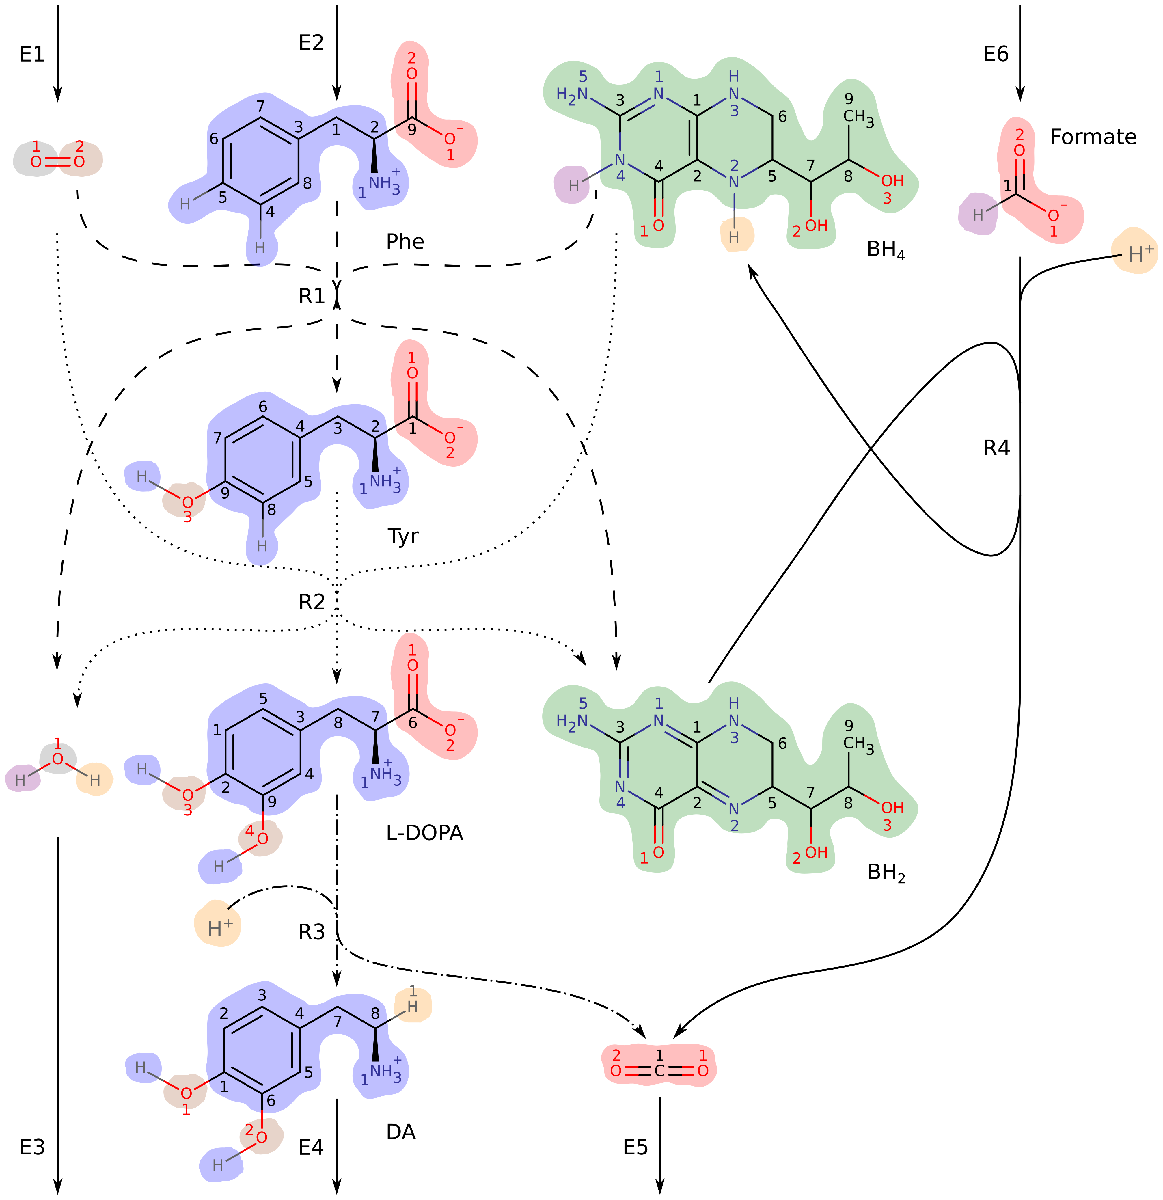

Figure 1: DAS: a small metabolic network consisting of reactions in the human dopamine synthesis pathway [2]. Atoms belonging to the same conserved moiety have identically coloured backgrounds.

## Part 1: Identify conserved moieties in DAS

**Step 1: Generate an atom transition network for DAS based on atom mappings for internal (mass and charge balanced) reactions.**

The atom transition network is generated based on the reconstructed DAS network (model) and atom mappings for internal reactions, contained in rxnfiles in Data/AtomMappingFiles (rxnfileDir). Atom mappings were predicted with the DREAM algorithm [3].

load Data/DAS.mat % The dopamine synthesis network
rxnfileDir = 'Data/AtomMappingFiles/'; % Manually edited atom mappings
ATN = buildAtomTransitionNetwork(model,rxnfileDir);


Atom mappings found for 4 model reactions.
Generating atom transition network for reactions with atom mappings.



The output variable (ATN) is a Matlab structure with several fields. ATN.A is the incidence matrix of the directed graph representing the atom transition network. Each row represents a particular atom in one of the 11 DAS metabolites. ATN.mets indicates which metabolite in DAS each atom belongs to. To find rows of ATN.A corresponding to atoms in H2O, run

ih2o = find(ismember(ATN.mets,'H2O'))'

ih2o =    112   113   114


The order of atoms in ATN.A matches their order in molfiles encoding metabolite structures (Figure 2), e.g., ATN.A(114,:) is the row corresponding to the second hydrogen atom (number 3 in Figure 2).

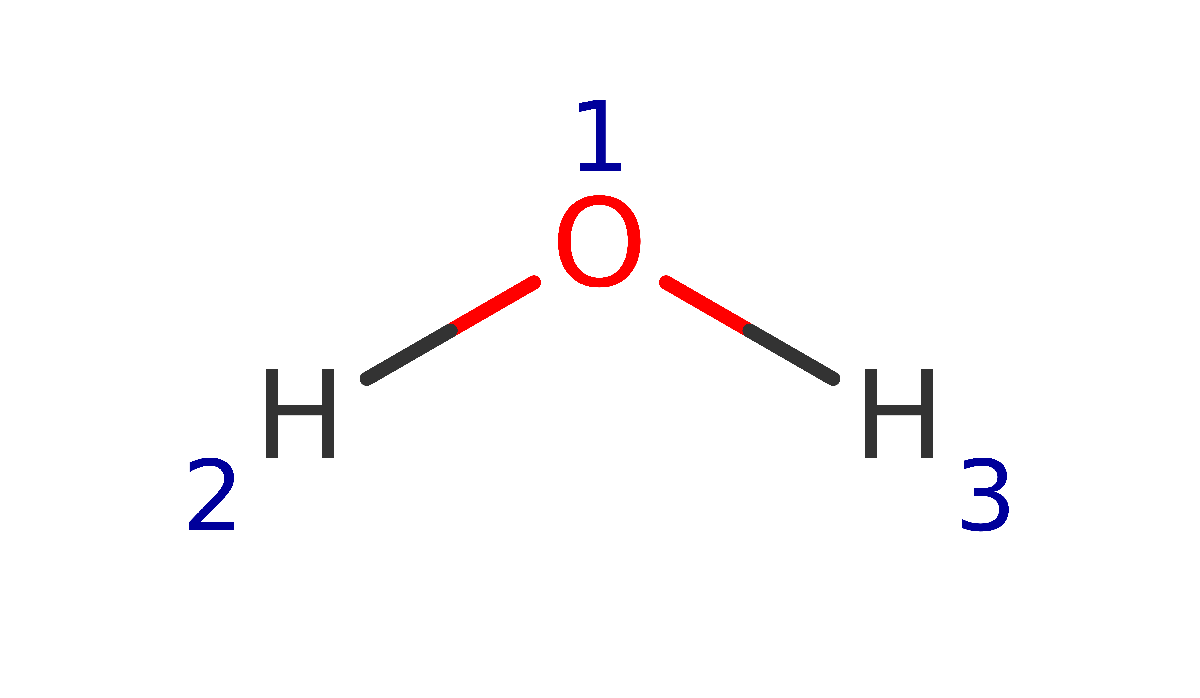

Figure 2: Rows for H2O atoms in ATN.A are ordered as shown.

ATN.elements contains the element symbols of atoms, e.g.,

ATN.elements{114}

ans = H

Each column of ATN.A represents a particular atom transition in one of the four internal reactions in DAS. Reaction identifiers of atom transitions are given in ATN.rxns. To find all atom transitions that involve H2O atoms, run

th2o = find(any(ATN.A(ih2o,:),1))

th2o =     41    43    57    75    77    91


ATN.rxns(th2o)'

ans =     'R1'    'R1'    'R1'    'R2'    'R2'    'R2'


i.e., three atom transitions in each of the reactions R1 and R2 involve atoms in H2O. To find atoms connected to H2O atoms via these atom transitions, run

ch2o = find(any(ATN.A(:,th2o) < 0,2));
ATN.mets(ch2o)'

ans =     'BH4'    'BH4'    'O2'


i.e., H2O atoms are connected to atoms in the metabolites BH4 and O2.

**Step 2: Identify conserved moieties in DAS by graph theoretical analysis of the atom transition network generated in Step 1.**

tic
[L,Lambda,moietyFormulas,moieties2mets,moieties2vectors,atoms2moieties] = identifyConservedMoieties(model,ATN);
t = toc;
fprintf('Computation time: %.1e s\n\n', t); % Print computation time

Computation time: 1.5e-01 s



This function outputs the moiety matrix (L), the moiety supergraph (Lambda), the chemical formulas of moieties (moietyFormulas), and three vectors that map between the various inputs and outputs. The 11×7 moiety matrix L has a row for each metabolite and a column for each conserved moiety in DAS. Each column is a moiety vector, with elements corresponding to the number of instances of a conserved moiety in each metabolite. To find the number of instances of moiety 2 in L-DOPA, run

iLDOPA = find(ismember(model.mets,'L-DOPA'))

iLDOPA = 7

full(L(iLDOPA,2))

ans = 1

i.e., L-DOPA contains one instance of moiety 2.

The 26×24 moiety supergraph (Lambda) contains the graphs of all seven conserved moieties in DAS (Figure 3).

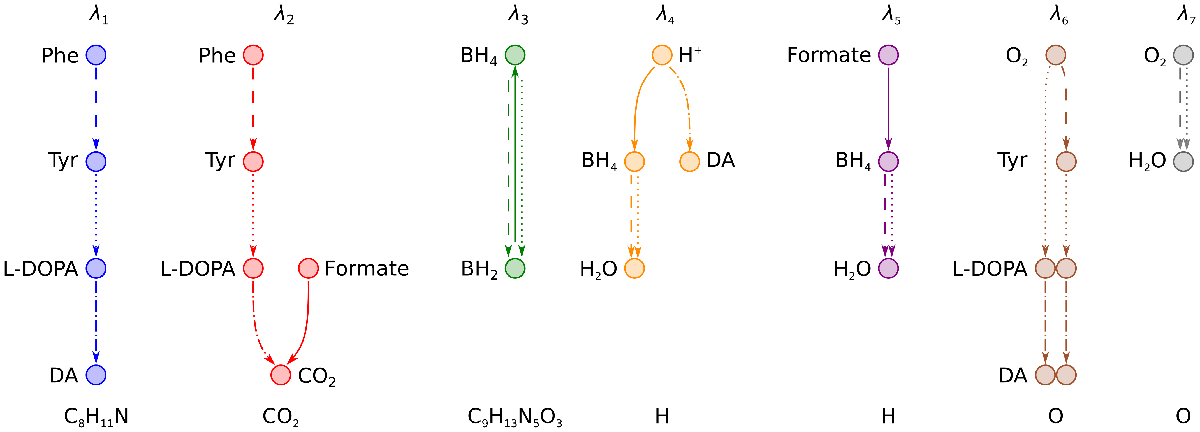

Figure 3: Graphs of the seven conserved moieties in DAS. Each node represents an instance of a conserved moiety in a particular metabolite. Each directed edge represents conservation of a moiety between two metabolites. The chemical formula of each moiety is given below its graph.

Each row of Lambda represents a single instance of a conserved moiety in a particular metabolite. The vector moieties2vectors maps between the rows of Lambda and the columns of L. To obtain the incidence matrix of a particular moiety graph, e.g., λ2 in Figure 3, run

i2 = find(moieties2vectors == 2);
c2 = find(any(Lambda(i2,:)));
lambda2 = full(Lambda(i2,c2))

lambda2 =     -1     0     0     0
     1    -1     0     0
     0     1    -1     0
     0     0     1     1
     0     0     0    -1


The vector moieties2mets maps the rows of Lambda to metabolite indices in the DAS reconstruction (model). To find metabolites containing instances of moiety 2, run

m2 = moieties2mets(i2);
mets2 = model.mets(m2)'

mets2 =     'Phe'    'Tyr'    'L-DOPA'    'CO2'    'Formate'


The chemical formula of moiety 2 is given by,

moietyFormulas{2}

ans = CO2

Finally, the vector atoms2moieties maps each atom in the atom transition network for DAS to a particular instance of a conserved moiety. To find atoms in L-DOPA that belong to moiety 2, run

find(ismember(atoms2moieties,i2) & ismember(ATN.mets,'L-DOPA'))'

ans =    120   121   125


**Step 3: Classify moieties**

types = classifyMoieties(L,model.S)

types =     'Transitive'
    'Transitive'
    'Internal'
    'Integrative'
    'Integrative'
    'Transitive'
    'Transitive'


The internal moiety (λ3 in Fig. 3) is conserved in both the open and closed DAS network, whereas the transitive and integrative moieties are only conserved in the closed network [4].

## Part 2: Effects of variable atom mappings between reoccurring metabolite pairs

Here, we will again identify conserved moieties in DAS but with a slightly different set of atom mappings (Figure 4). The different atom mappings give rise to a different atom transition network with a different set of conserved moieties. In particular, it contains a single composite moiety, λ8 in Figure 4, in place of the two moieties λ6 and λ7 in Figure 3. The composite moiety is the result of variable atom mappings between the reoccurring metabolite pair O2 and H2O in reactions R1 and R2.

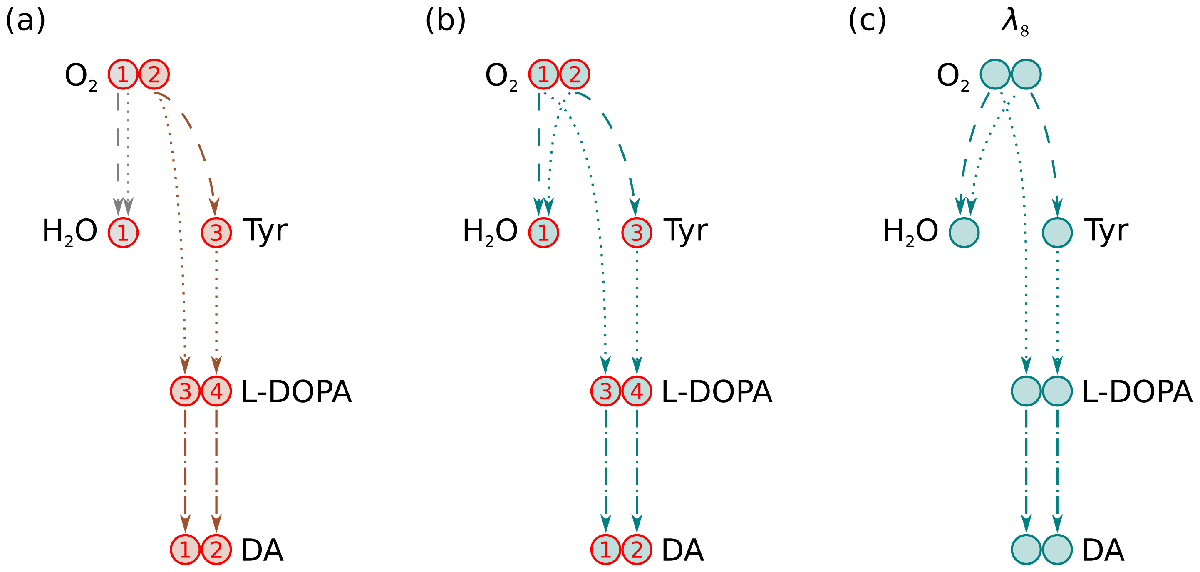

Figure 4: (a) Oxygen atom transitions used in Part 1. Oxygen atom 1 in O2 maps to the oxygen atom in H2O in both R1 and R2. These atom transitions contain two separate moieties, with two disconnected moiety graphs (λ6 and λ7 in Figure 3), and two linearly independent moiety vectors (L(:,6) and L(:,7)). (b) Oxygen atom transitions used in Part 2. A different oxygen atom maps from O2 to H2O in R1 than in R2. These atom transitions contain only one composite moiety. (c) The composite moiety graph arising from the oxygen atom transitions in (b).

**Step 1: Identify conserved moieties with the alternative set of atom mappings.**

load Data/DAS.mat
rxnfileDir = 'Data/AlternativeAtomMappingFiles/';
ATN = buildAtomTransitionNetwork(model,rxnfileDir);


Atom mappings found for 4 model reactions.
Generating atom transition network for reactions with atom mappings.



[L,Lambda,moietyFormulas,moieties2mets,moieties2vectors,atoms2moieties] = identifyConservedMoieties(model,ATN);

Apart from the rxnfile directory, these commands are identical to those used in Steps 1 and 2 in Part 1. The moiety matrix L now contains only six moiety vectors (columns) in place of the seven moiety vectors obtained in part 1. The sixth moiety vector represents the composite moiety (λ8 in Figure 4).

full(L(:,6)')

ans =      0     0     2     1     0     1     2     0     2     0     0


**Step 2: Decompose the composite moiety vector**

First, extract the internal stoichiometric matrix for DAS, by running

rbool = ismember(model.rxns,ATN.rxns);
mbool = any(model.S(:,rbool),2);
N = model.S(mbool,rbool);

To decompose the moiety matrix computed in Step 1, run

changeCobraSolver('gurobi6','milp');
D = decomposeMoietyVectors(L,N);

Note that you can use any MILP solver that is supported by the COBRA toolbox. The decomposed moiety matrix D is identical to the original moiety matrix computed in Part 1. Moiety vectors D(:,6) and D(:,7) are the linearly independent components of the composite moiety vector L(:,6) above.

full(D(:,[6 7])')

ans =      0     0     1     0     0     1     0     0     0     0     0
     0     0     1     1     0     0     2     0     2     0     0


One disadvantage of decomposing moiety vectors is that it is difficult to keep track of which atoms belong to the decomposed moieties. We can, however, estimate the chemical formulas of the decomposed moieties using the elemental matrix for DAS. The elemental matrix is a numerical representation of the chemical formulas of metabolites in DAS.

load Data/elementalMatrix.mat
decomposedMoietyFormulas = estimateMoietyFormulas(D,E,elements);
decomposedMoietyFormulas([6 7])'

ans =     'O'    'O'


i.e., each decomposed moiety consists of a single oxygen atom.

## References

[1] Hulda S. Haraldsdóttir and Ronan M. T. Fleming. Identification of conserved moieties in metabolic networks by graph theoretical analysis of atom transition networks. PLOS Computational Biology, 12(11): e1004999, 2016.

[2] Ines Thiele, Neil Swainston, Ronan M. T. Fleming, et al. A community-driven global reconstruction of human metabolism. Nature Biotechnology, 31(5):419–425, 2013.

[3] Eric L. First, Chrysanthos E. Gounaris, and Christodoulos A. Floudas. Stereochemically Consistent Reaction Mapping and Identification of Multiple Reaction Mechanisms through Integer Linear Optimization. Journal of Chemical Information and Modeling, 52(1):84–92, 2012.

[4] Iman Famili and B. Ø. Palsson. The convex basis of the left null space of the stoichiometric matrix leads to the definition of metabolically meaningful pools. Biophysical Journal, 85(1):16–26, 2003.